% 3-DOF Leg Workspace
% Kai De La Cruz 6/27/2025
% add comparison to previous 2 DOF leg

% Workspace calculation for 3-DOF leg
L1 = 2.285 * 0.3048; % [m]
L2 = 4.77 * 0.3048;
L3 = 5.75 * 0.3048; 
L4 = 6.125 * 0.3048;

theta1_range = -90:20:90; % Revolute joint 1 sweep
theta2_range =  0:20:360; % Revolute joint 2 sweep
theta3_range =  0:20:135; % Revolute joint 3 sweep

all_points = [];   % Stores all end-effector positions

for theta1 = theta1_range
    for theta2 = theta2_range
        for theta3 = theta3_range
            % Convert degrees to radians for trigonometric functions
            th1 = deg2rad(theta1);
            th2 = deg2rad(theta2);
            th3 = deg2rad(theta3);
            
            % Compute each transformation
            A0 = transform(+pi/2, 0, 0, +pi/2);
            A1 = transform(th1-(pi/2), L1, 0, -pi/2);
            A2 = transform(th2-(pi/2), L2, L3, 0);
            A3 = transform(th3, 0, L4, 0);
            
            % Full transformation from base to end effector
            T = A0 * A1 * A2 * A3;
            
            % Extract end effector position (first three entries of the last column)
            x = T(1,4);
            y = T(2,4);
            z = T(3,4);
            
            % Store the point
            all_points = [all_points; x, y, z];
        end
    end
end

% Workspace calculation for 2-DOF leg
L3 = 5.372 * 0.3048; 
L4 = 6.125 * 0.3048;

theta2_range2 =  0:10:360; % Revolute joint 2 sweep
theta3_range2 =  0:10:135; % Revolute joint 3 sweep

all_points2 = [];   % Stores all end-effector positions

for theta2 = theta2_range2
    for theta3 = theta3_range2
        % Convert degrees to radians for trigonometric functions
        th2 = deg2rad(theta2);
        th3 = deg2rad(theta3);
        
        % Compute each transformation
        A0 = transform(+pi/2, 0, 0, +pi/2);
        A1 = transform(-pi/2, 0, 0, -pi/2);
        A2 = transform(th2-(pi/2), 0, L3, 0);
        A3 = transform(th3, 0, L4, 0);
        
        % Full transformation from base to end effector
        T = A0 * A1 * A2 * A3;
        
        % Extract end effector position (first three entries of the last column)
        x = T(1,4);
        y = T(2,4);
        z = T(3,4);
        
        % Store the point
        all_points2 = [all_points2; x, y, z];
    end
end

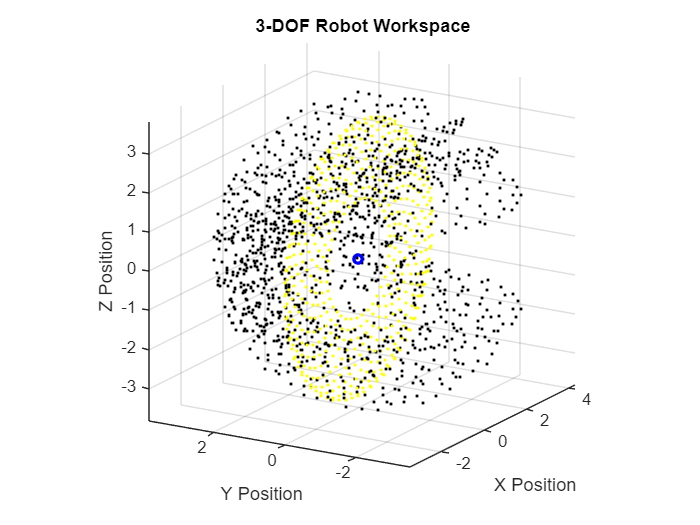

% Plot all possible points
figure;
plot3(all_points(:,1), all_points(:,2), all_points(:,3), 'k.', 'MarkerSize', 5);    %3dof WS
hold on;
plot3(all_points2(:,1), all_points2(:,2), all_points2(:,3), 'y.', 'MarkerSize', 5);     %2dof WS
plot3(0, 0, 0, 'bo', 'MarkerSize', 5, 'LineWidth', 2);
xlabel('X Position'); 
ylabel('Y Position'); 
zlabel('Z Position');
grid on;
axis equal;
title('3-DOF Robot Workspace');
view([-59.08 17.50])


function A = transform(theta, d, a, alpha)
% transform generate a 4X4 matix based off DH parameters
% from n to n+1
% this computation will be in terms of radians

A = [cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta);
    sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
    0, sin(alpha), cos(alpha), d;
    0, 0, 0, 1];

end

